### **Setting up data for examples**

We'll make some dummy data here for the examples - imagine you loaded in your data, latitude and longitude arrays from a file 

% make dummy gridded data
lon=[-179:2:179]';
lat=flipud([-89.0110:1.9780:89.0110]');
data_gridded=peaks(180); data_gridded=data_gridded(1:91,:);
[lon_gridded,lat_gridded]=meshgrid(lon,lat);

% make dummy point observation data
lon_point=[7.58
-88.47
71.9
-17.92
-73.09
7.58
-17.37
-66.550
-35.18
71.90];

lat_point=[43.5600
   25.6700
  -49.9000
   42.4200
  -34.0500
   43.5600
   43.2500
   32.9200
  -20.9300
  -48.4100];

data_point=rand(10,1);


### **Example 1: Display RECCAP2 regions and numbering**

Call the get_RECCAP_region function with no inputs:

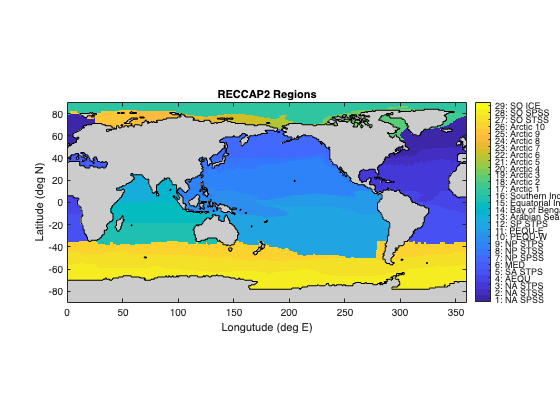

Region indices and names: 
1: NA SPSS 
2: NA STSS 
3: NA STPS 
4: AEQU 
5: SA STPS 
6: MED 
7: NP SPSS 
8: NP STSS 
9: NP STPS 
10: PEQU-W 
11: PEQU-E 
12: SP STPS 
13: Arabian Sea 
14: Bay of Bengal 
15: Equatorial Indian 
16: Southern Indian 
17: Arctic 1 
18: Arctic 2 
19: Arctic 3 
20: Arctic 4 
21: Arctic 5 
22: Arctic 6 
23: Arctic 7 
24: Arctic 8 
25: Arctic 9 
26: Arctic 10 
27: SO STSS 
28: SO SPSS 
29: SO ICE 


% get a plot of the base RECCAP2 regions and print indices & names to screen
get_RECCAP_region();

### **Example 2: Basic masking with regions**

#### **Using gridded data**

Pass gridded latitude and longitude directly into the get_RECCAP_region function:

[regions,regions_names]=get_RECCAP_region(lat_gridded,lon_gridded);

Let's plot the regions to see:

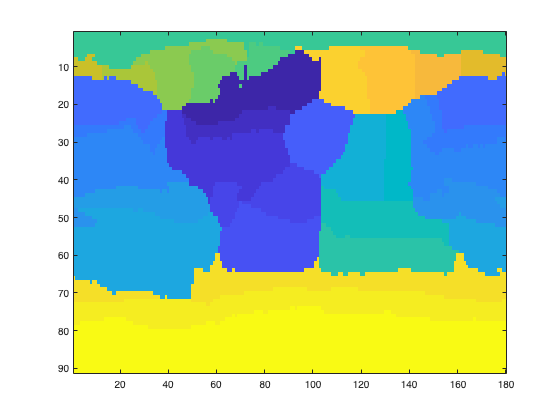

figure
imagesc(regions)

Regions are interpolated over land - you're looking at a map centred on 0 deg E, the Atlantic is the dark blue, SO in yellow

To select all the data in a region into a 1D array (good for calculating summary values and statistics):

data_plot=data_gridded(regions==1); % select all data in region 1
data_plot(1:10) % demonstrate this comes out as a vector

ans =     0.0021
    0.0031
   -0.0066
   -0.0063
   -0.0162
   -0.0170
   -0.0175
   -0.0175
   -0.0276
   -0.0294


To mask out a region if your data is gridded (good for mapping):

data_copy=data_gridded; % make a copy of data
data_copy(regions~=1)=NaN; % set everywhere not region to NaN

% make basic plots to demonstrate
figure
subplot(3,1,1)
imagesc(data_gridded)
title('All Data')
caxis([-6 3])
subplot(3,1,2)
imagesc(data_copy)
title('Region 1')
caxis([-6 3])

To mask out more than region:

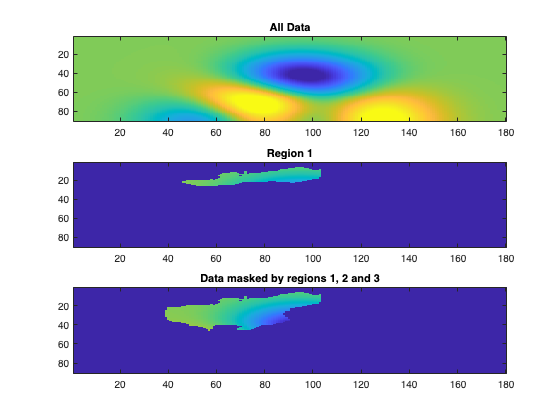

data_copy=data_gridded; 
data_copy(regions~=1 & regions~=2 & regions~=3)=NaN;

subplot(3,1,3)
imagesc(data_copy)
title('Data masked by regions 1, 2 and 3')
caxis([-6 3])

#### Using point data

If you have point-based data, e.g., a list of observations at discrete locations, the approach is very similar:

[regions,regions_names]=get_RECCAP_region(lat_point,lon_point);
data_masked=data_point(regions==3); % keep all data in region 3



### **Example 3: Basic calculations using region masks**

This example demonstrates how to calculate summary statistics, e.g., mean or sum, using the region masks.

With gridded data, vectorising the data is a good approach for single value summaries for each region:

% get regions from grid
[regions,regions_names]=get_RECCAP_region(lat_gridded,lon_gridded);
% reshape grid into a single vector
data_vec=reshape(data_gridded,[],1);
region_vec=reshape(regions,[],1);


You can apply functions like mean or sum using the splitapply function to do calculations over all regions:

% calculate mean value for each region
data_region_mean=splitapply(@mean,data_vec,region_vec)

data_region_mean =    -0.9708
   -1.4589
   -1.5070
   -3.9169
   -0.4638
   -3.8464
    0.0024
   -0.0022
   -0.0095
    0.0278


### **Example 4: Merging RECCAP2 regions **

You can merge regions together by passing in extra inputs as pairs: 1) <new region name> 2) <region id numbers to combine into new region>

Here we'll merge all the Arctic regions into one:

% let's merge all Arctic regions (id = 17 to 26)
[regions_arctic,regions_names]=get_RECCAP_region(lat_gridded,lon_gridded,'Arctic',[17 18 19 20 21 22 23 24 25 26]);

You can add multiple pairs in one go for multiple new regions. Here we'll merge regions into ocean basins:

% let's merge everything into basins
[regions_basins,regions_names]=get_RECCAP_region(lat_gridded,lon_gridded,'Atlantic',[1:6],'Pacific',[7:12],'Indian',[13:16],'Arctic',[17:26],'SO',[27:29]);

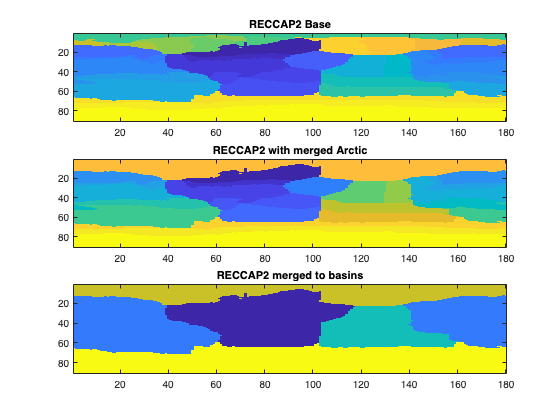

% plot regions to see difference
figure
subplot(3,1,1)
imagesc(regions);
title('RECCAP2 Base')

subplot(3,1,2)
imagesc(regions_arctic);
title('RECCAP2 with merged Arctic')

subplot(3,1,3)
imagesc(regions_basins)
title('RECCAP2 merged to basins')



% show region names have been updated (last run with basins merge)
regions_names

regions_names = 1×5 cell array
    {'Atlantic'}    {'Pacific'}    {'Indian'}    {'Arctic'}    {'SO'}


#### Extracting the JETZON Biological Pump benchmark analysis regions

These region definitions are hard-coded into the function and can be extracted using:

[regions,regions_names]=get_RECCAP_region(lat_gridded,lon_gridded,'jetzon');

### **Example 5: Mapping regions**

This example demonstrates how to make a variable containing region definitions that can be used as a map, e.g., plotting.

You need longitude and latitude vectors. Either take predefined longitude and latitude vectors, e.g., from World Ocean Atlas or a model grid, or define them from scratch:

% longitude and latitude vectors
lon=[-179:2:179]';
lat=flipud([-89.0110:1.9780:89.0110]');


We need to generate pairs of lon & lat values for each grid location from the single dimension vectors and pass this to the function:

[lon_gridded,lat_gridded]=meshgrid(lon,lat);
[regions_basins,regions_names]=get_RECCAP_region(lat_gridded,lon_gridded);

You can now plot the regions_basins array:

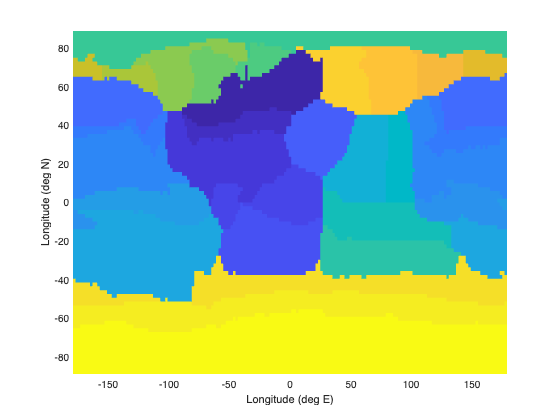

pcolor(lon,lat,regions_basins); shading flat;
xlabel('Longitude (deg E)')
ylabel('Longitude (deg N)')

*Note: this approach requires you to mask the land back over, which in this simple approach we don't have. You could use the m_map package or the mapping toolbox to achieve this.*

#### Mapping with m_map

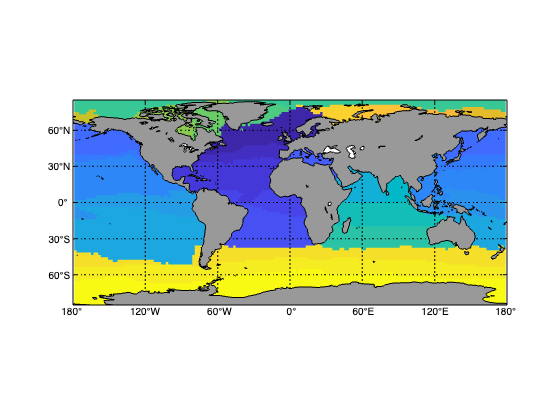

m_proj('Equidistant Cylindrical')
m_pcolor(lon,lat,regions_basins);
m_grid;
m_coast('patch',[.6 .6 .6]);